## 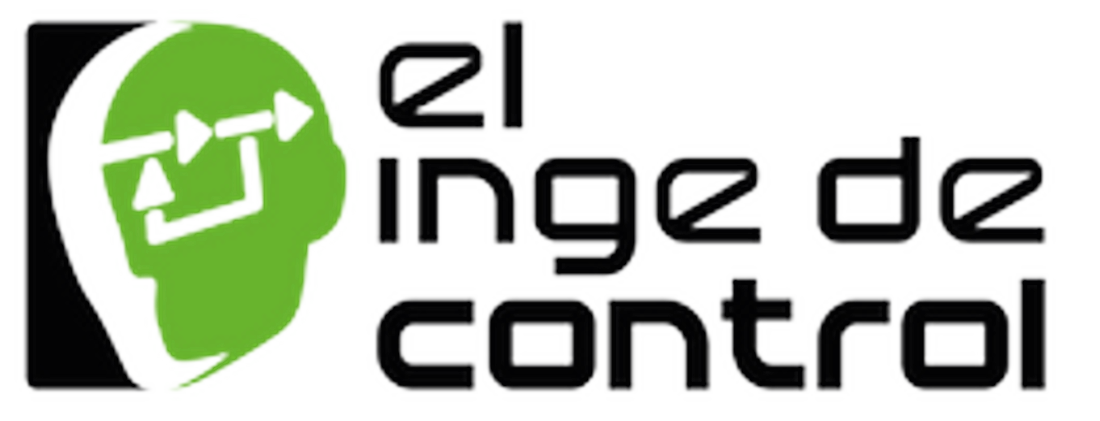

# **Taller: Control Robusto y Estocástico**

## Tema: Control ${\mathcal{H}}_{\infty }$de información completa

## Dr. Julio A. García Rodríguez

Ejercicio 01. $\mathcal{H}_2$

clc, clear all, close all

Set random seed for reproducibility

rng(6, 'twister')

Generate a random state-space system and transpose it. This command creates a 4-output, 5-input stable model and then takes its Hermitian conjugate. This operation yields a 5-output, 4-input unstable model

P = rss(3, 4, 5)';  % 3 states, 5 inputs, 4 outputs → transposed: 4 inputs, 5 outputs
pole(P)             % Confirm that P is unstable. All the poles are in the right half-plane.

ans =    1.7293 + 2.3295i
   1.7293 - 2.3295i
   1.8884 + 0.0000i


Display state-space matrices

A = P.A

A =     2.5969   -0.3441    0.3121
   25.5309   -6.2226   10.4055
   17.2314   -5.7885    8.9727


B = P.B

B =    -2.1226    0.6590    0.5933    0.3933
         0   -0.6669    0.3637   -1.2794
    0.2630    0.5020   -0.4564    1.5617


C = P.C

C =          0    0.7818    0.8258
    0.6028    0.1371   -0.5352
         0   -0.2003   -1.2654
    0.6379    1.5989   -1.0382
    0.6877    0.3886         0


D = P.D

D =    -0.1285         0         0         0
   -0.5538         0   -0.5770    0.5146
         0   -0.5559         0    0.3753
         0         0    1.6460         0
         0         0         0         0


disp('Matrix A:'); disp(A);

Matrix A:
    2.5969   -0.3441    0.3121
   25.5309   -6.2226   10.4055
   17.2314   -5.7885    8.9727



disp('Matrix B:'); disp(B);

Matrix B:
   -2.1226    0.6590    0.5933    0.3933
         0   -0.6669    0.3637   -1.2794
    0.2630    0.5020   -0.4564    1.5617



disp('Matrix C:'); disp(C);

Matrix C:
         0    0.7818    0.8258
    0.6028    0.1371   -0.5352
         0   -0.2003   -1.2654
    0.6379    1.5989   -1.0382
    0.6877    0.3886         0



disp('Matrix D:'); disp(D);

Matrix D:
   -0.1285         0         0         0
   -0.5538         0   -0.5770    0.5146
         0   -0.5559         0    0.3753
         0         0    1.6460         0
         0         0         0         0



Controllability and observability analysis

ctrbRank = rank(ctrb(A, B))

ctrbRank = 3

obsvRank = rank(obsv(A, C))

obsvRank = 3

Step Response

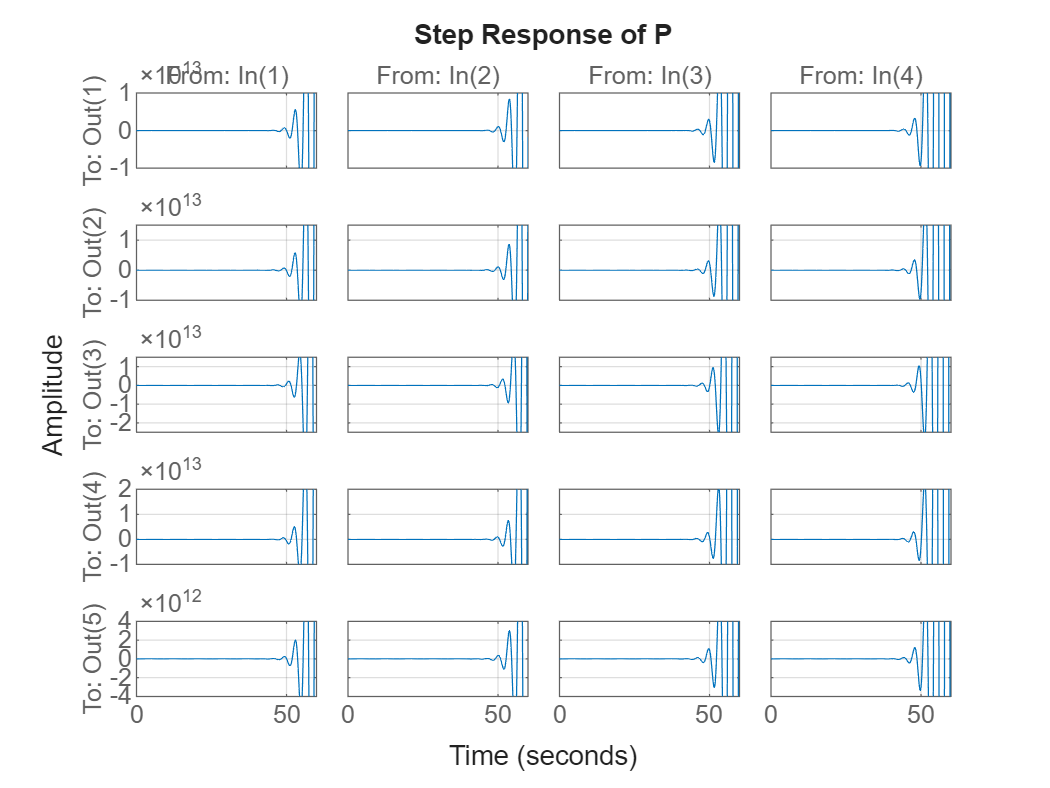

step(P)
title('Step Response of P');
grid on

Impulse response 

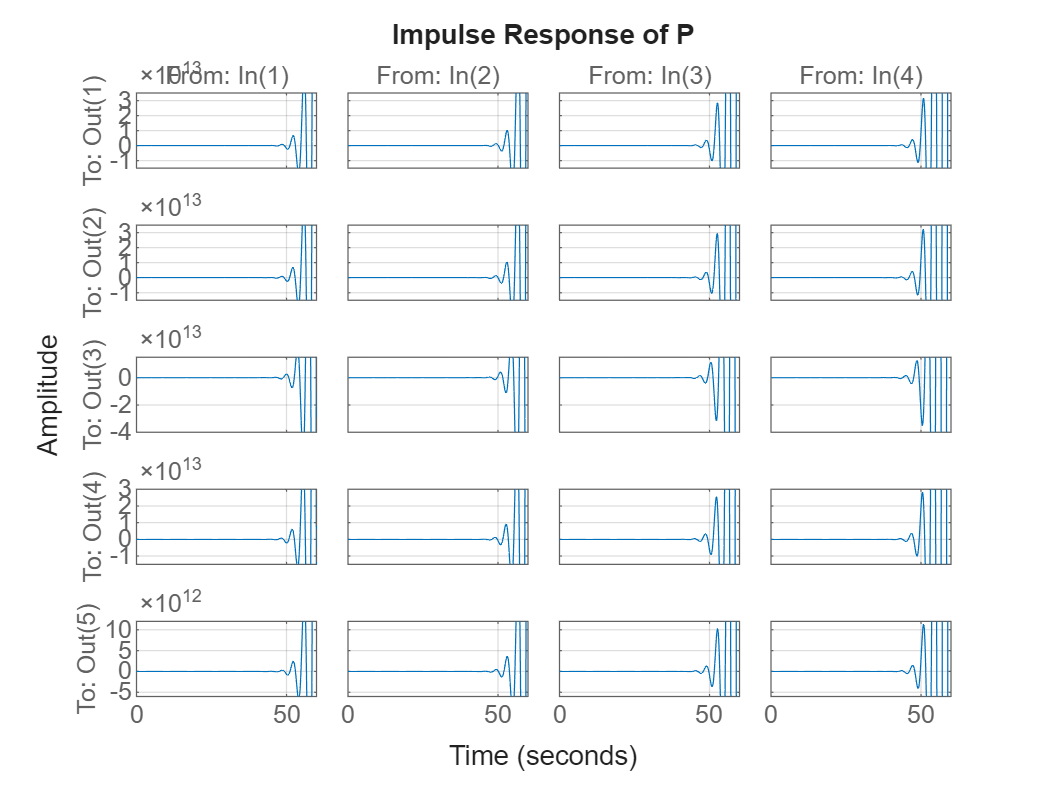

impulse(P)
title('Impulse Response of P');
grid on

Frequency response (Bode plot)

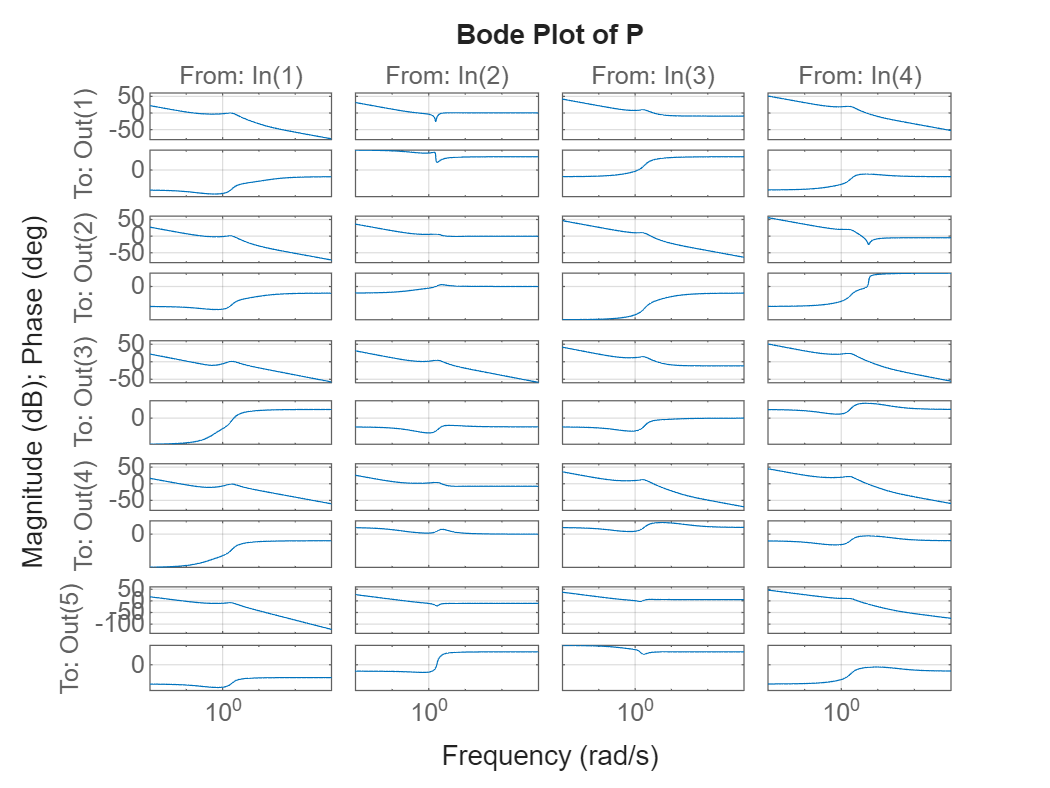

bode(P)
title('Bode Plot of P');
grid on

 Pole-zero map

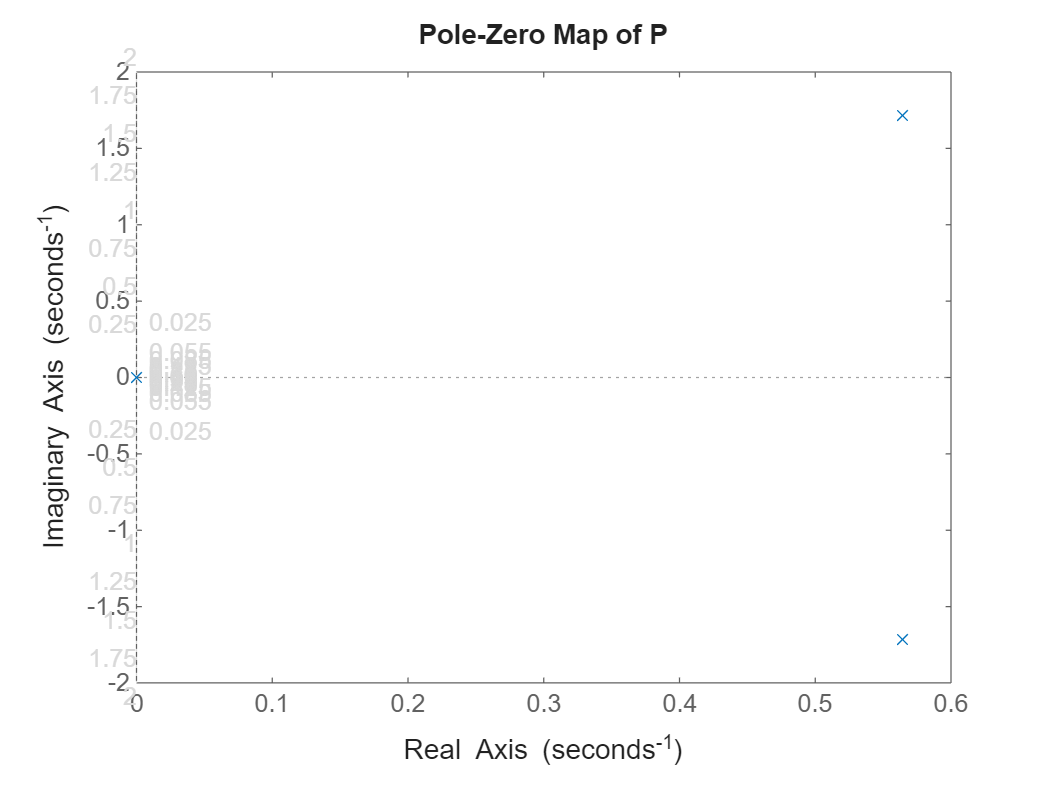

pzmap(P)
title('Pole-Zero Map of P');
grid on

Controller synthesis

[K,CL,GAM] = h2syn(P,2,1);

disp('Controller K:'); disp(K); K

Controller K:
  1×2 ss array with properties:

                A: [3×3 double]
                B: [3×2 double]
                C: [214.2383 22.0389 -50.4440]
                D: [0.4447 0]
                E: []
          Offsets: []
           Scaled: 0
        StateName: {3×1 cell}
        StatePath: {3×1 cell}
        StateUnit: {3×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [2×1 double]
      OutputDelay: 0
        InputName: {2×1 cell}
        InputUnit: {2×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]


K =
 
  A = 
               x1          x2          x3
   x1  -2.765e+07  -1.562e+07      -17.32
   x2   7.159e+05   4.046e+05       71.93
   x3  -3.508e+06  -1.983e+06      -76.

disp('Closed-Loop CL:'); disp(CL);

Closed-Loop CL:
  3×3 ss array with properties:

                A: [6×6 double]
                B: [6×3 double]
                C: [3×6 double]
                D: [3×3 double]
                E: []
          Offsets: []
           Scaled: 0
        StateName: {6×1 cell}
        StatePath: {6×1 cell}
        StateUnit: {6×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [3×1 double]
      OutputDelay: [3×1 double]
        InputName: {3×1 cell}
        InputUnit: {3×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {3×1 cell}
       OutputUnit: {3×1 cell}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]



disp('Gamma:'); disp(GAM);

Gamma:
   Inf



pole(CL)
Ak=K.A;
Bk=K.B;
Ck=K.C;
Dk=K.D;